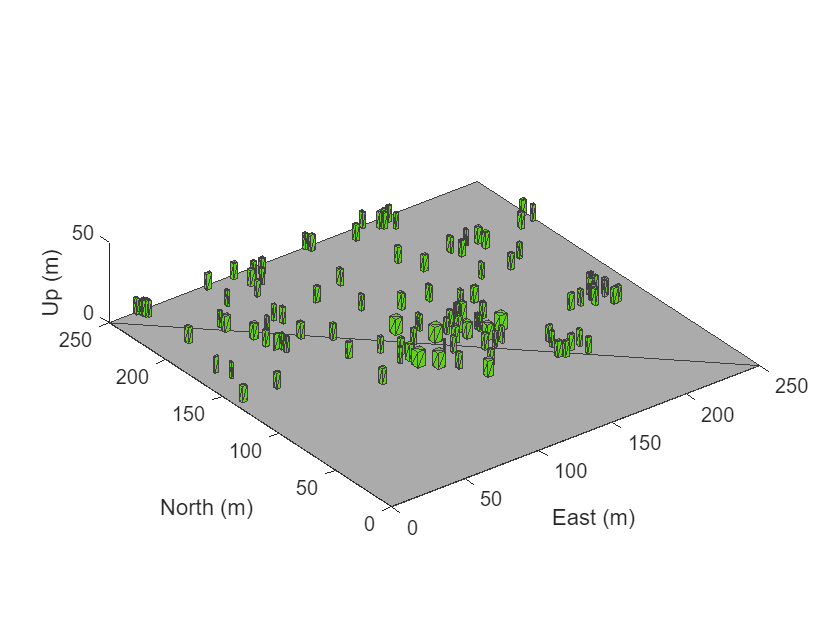

% Create the UAV scenario.
scene = uavScenario(UpdateRate=2,ReferenceLocation=[75 -46 0]);

% Add a ground plane.
color.Gray = 0.651*ones(1,3);
color.Green = [0.3922 0.8314 0.0745];
color.Red = [1 0 0];
addMesh(scene,"polygon",{[0 0; 250 0; 250 250; 0 250],[-4 0]},color.Gray)

% load the data
load('../data/matlab_meshes/city_0.mat')

% Add sets of polygons as extruded meshes with varying heights from 10-30.
for i = 1:size(buildingCoords,2)
addMesh(scene,"polygon",{buildingCoords{i}(1:4,:),[0 10]},color.Green)
end
%addMesh(scene,"polygon",{[100,100; 100 150;200 150;200 100],[0 10]},color.Green)
% Show the scenario.
show3D(scene);
xlim([0 250])
ylim([0 250])
zlim([0 50])

% Set up platform
plat = uavPlatform("UAV",scene,ReferenceFrame="NED",...
    InitialPosition=[110,110,1],InitialOrientation=eul2quat([0 0 0]));

% Set up platform mesh. Add a rotation to orient the mesh to the UAV body
% frame.
updateMesh(plat,"quadrotor",{10},color.Red,[0 0 0],eul2quat([0 0 pi]))

lidarmodel = uavLidarPointCloudGenerator(AzimuthResolution=0.3324099,...
    ElevationLimits=[-20 20],ElevationResolution=1.25,...
    MaxRange=90,UpdateRate=2,HasOrganizedOutput=true);

lidar = uavSensor("Lidar",plat,lidarmodel,MountingLocation=[0,0,-1]);

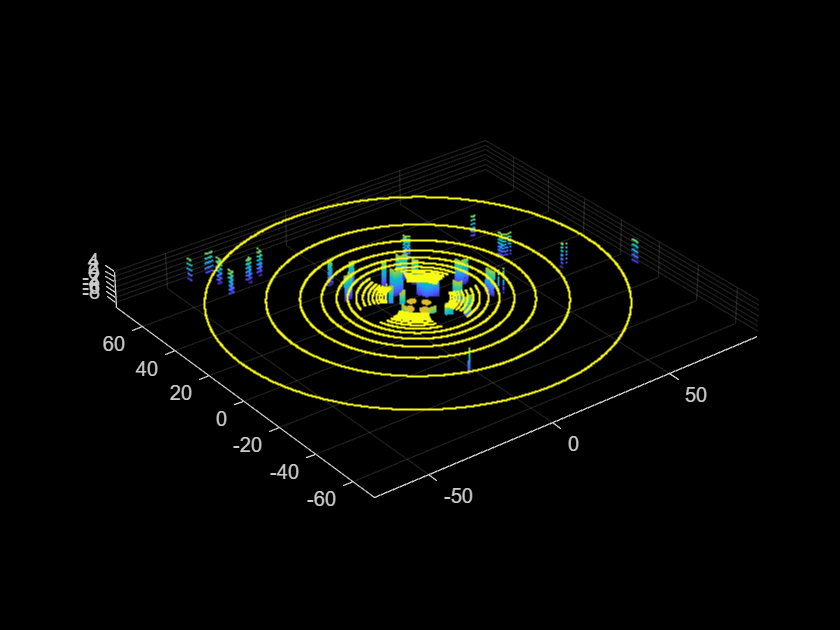

pt = pointCloud(nan(1,1,3));
setup(scene)
updateSensors(scene)

[isupdated,lidarSampleTime, pt] = read(lidar);
refreshdata
pcshow(pt)


flat_pointCloud = reshape(pt.Location,32*1083,3)

flat_pointCloud =    -3.0029    0.0000   -1.0930
   -3.0034    0.0000   -1.0172
   -3.0047    0.0000   -0.9427
   -2.9992    0.0000   -0.8673
   -2.9992    0.0000   -0.7946
   -2.9992    0.0000   -0.7227
   -3.0000    0.0000   -0.6518
   -3.0014    0.0000   -0.5817
   -3.0018    0.0000   -0.5119
   -3.0048    0.0000   -0.4430


writematrix(flat_pointCloud,'pt.csv')